Example 1: Window Functions


% Define window length and number of samples for fft
M = 64; % Choose an appropriate window length
n = -M/2 : M/2 - 1;
NFFT = 1024;

% Window functions
hanning_window = hanning(M);
hamming_window = hamming(M);
blackman_window = blackman(M);
blackmanharris_window = blackmanharris(M);
chebwin_window = chebwin(M, 30); % 30 dB sidelobe attenuation, you can adjust

% Plot the frequency response of each window
figure;
subplot(2, 1, 1);
plot(n, hanning_window, n, hamming_window, n, blackman_window, n, blackmanharris_window, n, chebwin_window);
title('Time Domain Representation of Window Functions');
xlabel('Sample');
ylabel('Amplitude');
legend('Hanning', 'Hamming', 'Blackman', 'Blackman-Harris', 'Chebwin');
grid on;

subplot(2, 1, 2);
X1 = fftshift(fft(hanning_window, NFFT));
Freq = (-NFFT/2 : NFFT/2 - 1) / NFFT;
Y1 = X1(1 : length(Freq)) / max(X1);
mag_dB = 10 * log10(Y1);
plot(Freq, mag_dB);

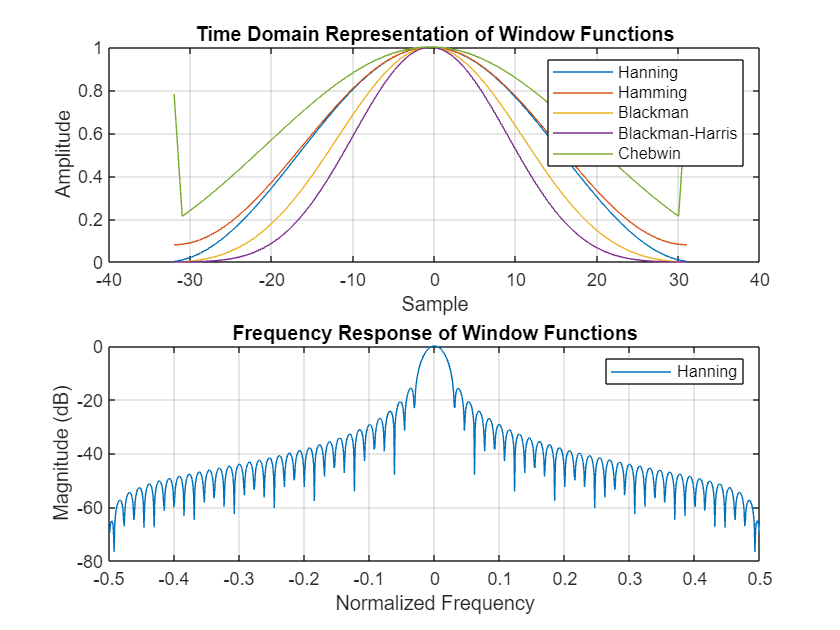


title('Frequency Response of Window Functions');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('Hanning');
grid on;

Example 2: Short-Time Fourier Transform ANALYSIS

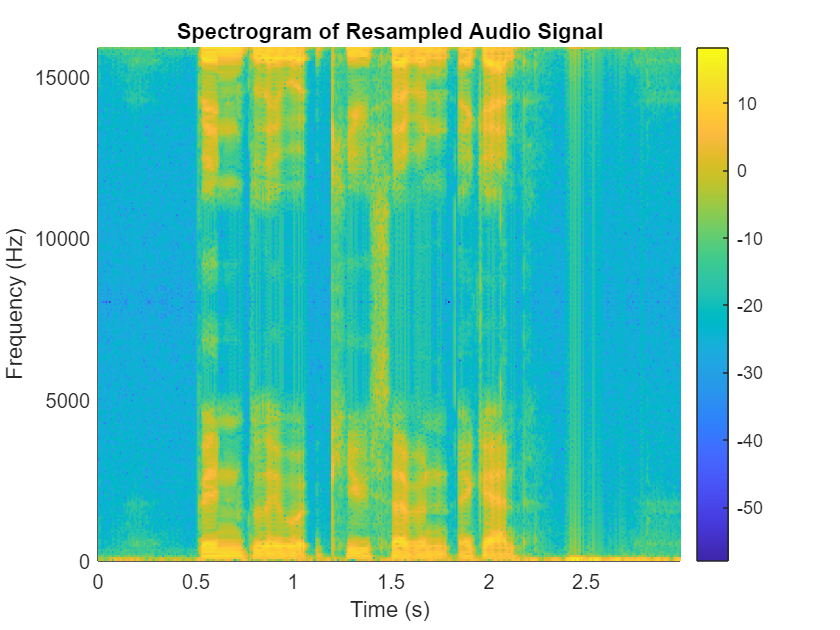

% (a) Reading and resampling an audio file
filename = 'speechfiles/bbaq7a.wav'; % Replace with the actual path to your file
[y, originalFs] = audioread(filename);

targetFs = 16000; % Target sampling rate
y_resampled = resample(y, targetFs, originalFs);



% (c) Analyzing the Time-Frequency representation
% Choose appropriate parameters
windowSize = 256;
overlapFactor = 0.5;

% Apply STFT to the resampled signal
[X_stft, timeVector, freqVector] = stft_ece(y_resampled, hamming(windowSize), overlapFactor, targetFs);

% Plot the spectrogram
figure;
pcolor(timeVector, freqVector, 10 * log10(abs(X_stft)));
shading 'flat';
title('Spectrogram of Resampled Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;


sound(y,originalFs)


% (Optional) Play the resampled audio
sound(y_resampled, targetFs);


run_stft

Error using pcolor
Matrix dimensions must agree.

Error in run_stft (line 28)
p = pcolor(vecT, vecF, 10 * log10(abs(X_stft(1:end/2, :))));